%% Start
disp("===============================START=====================================")

===============================START=====================================



clear
close all
clc

%% Load the market data
yahooDataSetUp = YahooDataSetUp;
yahooDataSetUp.path = pwd;
spreadSheetSetUp = SpreadSheetSetUp;
matFileSetUp = MatFileSetUp;
matFileSetUp.path = pwd;

marketData = MarketData (yahooDataSetUp, spreadSheetSetUp, matFileSetUp);
marketData = marketData.loadDataFromMatFile;
marketData = marketData.loadSymbolMCapRef;

marketData = marketData.classifyMktCap;

marketData = struct(marketData)

marketData = struct with fields:
       yahooDataSetUp: [1×1 YahooDataSetUp]
     spreadSheetSetUp: [1×1 SpreadSheetSetUp]
         matFileSetUp: [1×1 MatFileSetUp]
      priceVolumeData: {[3021×709 timetable]  [3021×709 timetable]  [3021×709 timetable]  [3021×709 timetable]  [3021×709 timetable]}
                 nDay: 1500
              symbols: [709×1 string]
            indexIHSG: []
            marketCap: [3021×709 timetable]
    marketCapCategory: [3021×709 timetable]
      symMarketCapRef: [709×6 table]
    marketCapRangeRef: [6×5 table]
          exhangeName: "JK"
     priceChangeLimit: [-0.3500 0.3500]
          nDayPerYear: 252


dataInput = marketData.priceVolumeData;

%% Load setting and preparation

paramSetWFA = setUpWFAParam(marketData, nWalk=6)

paramSetWFA = struct with fields:
                      nWalk: 6
                 lookbackUB: 300
                 nstepTrain: 240
                  nstepTest: 20
            walkPeriodTable: [6×17 table]
          walkMCapNSymTable: [6×7 timetable]
              walkMCapTable: {[6×710 timetable]  [6×710 timetable]  [6×710 timetable]  [6×710 timetable]  [6×710 timetable]  [6×710 timetable]}
                 uniqMktCap: [6×1 string]
                tradingCost: [0.0015 0.0025]
           maxCapAllocation: 0.2000
              backShiftNDay: 1
                 maxFcnEval: 360
                      nVars: 11
          optimLookbackStep: 240
             maxDDThreshold: -0.1500
                 minPortRet: 1.1000
       minDailyRetThreshold: -0.3500
     minLast20DRetThreshold: -0.1000
     minLast60DRetThreshold: -0.0500
    minLast200DRetThreshold: 0
                  lbubConst: [11×2 double]
             minSharpeRatio: 2



clearvars marketData


mCap = "Lower Big Cap"

MktCap: 1 | Walk: 1
Starting parallel pool (parpool) using the 'local' profile ...
Preserving jobs with IDs: 1 5 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile local. To create 'myCluster' use 'myCluster = parcluster('local')'.
Connected to the parallel pool (number of workers: 6).
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 1 | Walk: 2
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 1 | Walk: 3
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 1 | Walk: 4
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 1 | Walk: 5
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
Mkt

perWalkResults = struct with fields:
    mCap: "Lower Big Cap"


mCapWalkResults = 1×6 cell array
    {1×1 struct}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


mCap = "Lower Mid Cap"

MktCap: 2 | Walk: 1
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 2 | Walk: 2
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 2 | Walk: 3
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 2 | Walk: 4
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 2 | Walk: 5
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 2 | Walk: 6
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


perWalkResults = struct with fields:
                    mCap: "Lower Mid Cap"
         optimTradeParam: [6×12 timetable]
    tradeSignalPerSymOST: [120×709 timetable]
               symRetOST: [120×709 timetable]
              portRetOST: [120×1 timetable]


mCapWalkResults = 1×6 cell array
    {1×1 struct}    {1×1 struct}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


mCap = "Lower Small Cap"

MktCap: 3 | Walk: 1
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 3 | Walk: 2
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 3 | Walk: 3
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 3 | Walk: 4
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 3 | Walk: 5
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 3 | Walk: 6
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


perWalkResults = struct with fields:
                    mCap: "Lower Small Cap"
         optimTradeParam: [6×12 timetable]
    tradeSignalPerSymOST: [120×709 timetable]
               symRetOST: [120×709 timetable]
              portRetOST: [120×1 timetable]


mCapWalkResults = 1×6 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {0×0 double}    {0×0 double}    {0×0 double}


mCap = "Upper Big Cap"

MktCap: 4 | Walk: 1
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 4 | Walk: 2
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 4 | Walk: 3
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 4 | Walk: 4
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 4 | Walk: 5
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 4 | Walk: 6
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


perWalkResults = struct with fields:
                    mCap: "Upper Big Cap"
         optimTradeParam: [6×12 timetable]
    tradeSignalPerSymOST: [120×709 timetable]
               symRetOST: [120×709 timetable]
              portRetOST: [120×1 timetable]


mCapWalkResults = 1×6 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {0×0 double}    {0×0 double}


mCap = "Upper Mid Cap"

MktCap: 5 | Walk: 1
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 5 | Walk: 2
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 5 | Walk: 3
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 5 | Walk: 4
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 5 | Walk: 5
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 5 | Walk: 6
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


perWalkResults = struct with fields:
                    mCap: "Upper Mid Cap"
         optimTradeParam: [6×12 timetable]
    tradeSignalPerSymOST: [120×709 timetable]
               symRetOST: [120×709 timetable]
              portRetOST: [120×1 timetable]


mCapWalkResults = 1×6 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {0×0 double}


mCap = "Upper Small Cap"

MktCap: 6 | Walk: 1
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 6 | Walk: 2
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 6 | Walk: 3
No solution found that satisfies the nonlinear constraints.
MktCap: 6 | Walk: 4
No solution found that satisfies the nonlinear constraints.
MktCap: 6 | Walk: 5
No solution found that satisfies the nonlinear constraints.
MktCap: 6 | Walk: 6


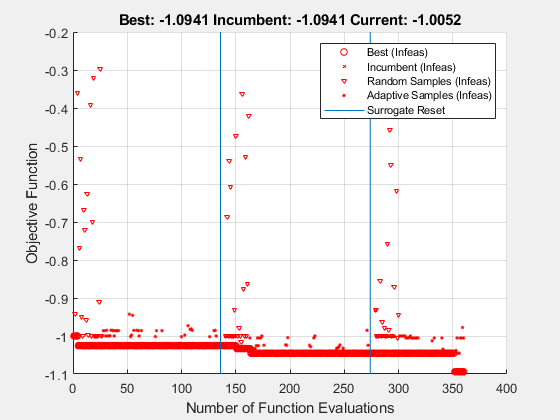

No solution found that satisfies the nonlinear constraints.


perWalkResults = struct with fields:
                    mCap: "Upper Small Cap"
         optimTradeParam: [6×12 timetable]
    tradeSignalPerSymOST: [120×709 timetable]
               symRetOST: [120×709 timetable]
              portRetOST: [120×1 timetable]


mCapWalkResults = 1×6 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


%% runWFA
tic
mCapWalkResults = runMCapWalk(dataInput, paramSetWFA)

runMCapWalkTime = toc

runMCapWalkTime = 9.1943e+03

% save mCapWalkResults
path = pwd;
folder = "DataOutput";
fileName = "mCapWalkResults.mat";
fullFileName = fullfile(path, folder,fileName);
save(fullFileName, "mCapWalkResults");

%% show performance evaluation
% plotPnL
% tiledlayout(2,1);
% 
% startDatePlot = paramSetWFA.walkPeriodTable(1,"startDateTest").Variables;
% endtDatePlot= paramSetWFA.walkPeriodTable(end,"endDateTest").Variables;
% rowTime = (startDatePlot:endtDatePlot)';
% 
% nexttile;
% portCumRetOSTPlot = ret2tick(perWalkResults.portRetOST(rowTime,:));
% plotPnL = plot(portCumRetOSTPlot.Time, portCumRetOSTPlot.Variables);
% title("portCumRetOST")
% 
% nexttile;
% tradeSignalPerSymOST = perWalkResults.tradeSignalOST;
% tradeSignalOST = tradeSignalPerSymOST(:,1);
% tradeSignalOST.Properties.VariableNames = "tradeSignalOST";
% tradeSignalOST.Variables = sum(tradeSignalPerSymOST.Variables,2);
% plot(tradeSignalOST.Time, tradeSignalOST.Variables);


%% show performance evaluation


%% End
disp("===============================END=====================================")

===============================END=====================================
